# Digital Communications by Phase-shift Keying

Dr. Matthew Nokleby, Wayne State University. ECE 4330, Fall 2018.

Probably the most popular method of digital communications is called **phase-shift keying**: the digital bits are encoded in the phase of a sinusoid. A common form of phase-shift keying is called QPSK, or **quaternary phase-shift keying**. Each symbol carried two bits, and is encoded in one of four possible phase values.

We visualize the phases as **constellation points** on the complex plane. Each symbol is represented as a point, which is mapped to a sinusoid of the appropriate phase and transmitted.

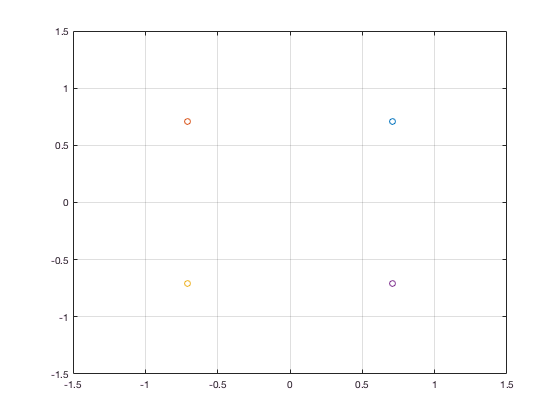

SAMPLE_RATE = 5*10^9;
SYMBOL_TIME = 4*10^-6;
CARRIER_FREQ = 2*10^6; %use 2.4*10^9 for WiFi

phases = [pi/4 3*pi/4 5*pi/4 7*pi/4];

close all;
for i=1:length(phases)
    plot(real(exp(1i*phases(i))),imag(exp(1i*phases(i))),'o');
    hold on;
end %for i
hold off;
grid;
axis([-1.5 1.5 -1.5 1.5])

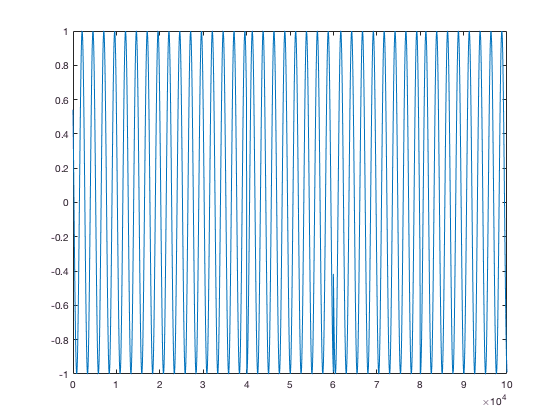

NUM_SYMBOLS = 5;

symbols = ceil(length(phases)*rand(NUM_SYMBOLS,1)); %generate random bits
x = [];
for i=1:NUM_SYMBOLS
    tValues = linspace(0,SYMBOL_TIME,SYMBOL_TIME*SAMPLE_RATE);
    this_symbol = real(exp(1i*(tValues*2*pi*CARRIER_FREQ + symbols(i))));
    x = [x this_symbol];
end %for i

plot(x);

You can see that the phase changes at every new symbol. We can plot this in the frequency domain for a more realistic signal containing many sample points.

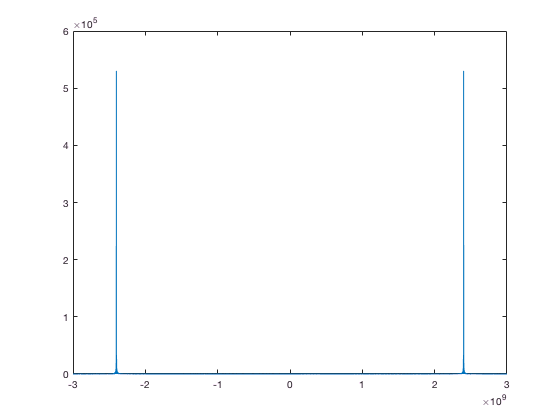

SAMPLE_RATE = 6*10^9;
SYMBOL_TIME = 4*10^-6;
CARRIER_FREQ = 2.4*10^9; %for WiFi

NUM_SYMBOLS = 100;

symbols = ceil(length(phases)*rand(NUM_SYMBOLS,1)); %generate random bits
x = [];
for i=1:NUM_SYMBOLS
    tValues = linspace(0,SYMBOL_TIME,SYMBOL_TIME*SAMPLE_RATE);
    this_symbol = real(exp(1i*(tValues*2*pi*CARRIER_FREQ + symbols(i))));
    x = [x this_symbol];
end %for i

X = fftshift(fft(x));
fValues = linspace(-SAMPLE_RATE/2,SAMPLE_RATE/2,length(x));

close all;
plot(fValues,abs(X));

We expect that the information is concentrated near the carrier frequency, but why isn't it *exactly* a delta function? The changes in phase make the signal not perfectly sinuoidal. In fact, the faster we signal, the quicker we change the phase, and the more bandwidth we use up. We can see this by adjusting the symbol time above. [Signaling faster also makes transmission much more susceptible to noise!]

Digital communications involves almost everything we've used in this class. In addition to understanding the magnitude and phase of the signal, it involves filtering the signal before transmission to avoid intereference, filtering the signal *after* transmission to counteract the impact of the channel.